# Farshad Bolouri - Homework II - Grad

## Problem 5)

#### Write a program in MATLAB /Python that:

a) Generates a 1-second test signal containing a 4Hz sinusoid and a 7Hz sinusoid added together, sampled at 64 samples/second

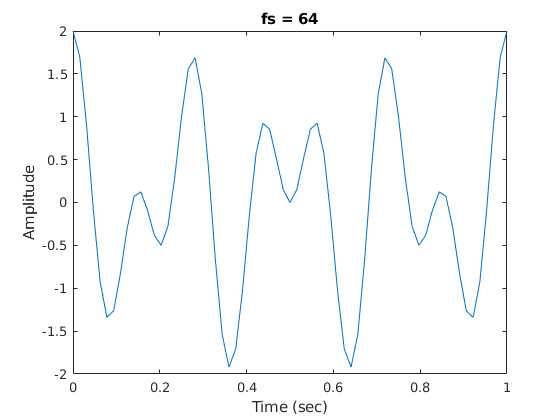

f1 = 4;         % 4Hz 
f2 = 7;         % 7Hz
t = 0:1/64:1;   % 1 second sampled at 64 samples/second

x = cos(2*pi*f1*t) + cos(2*pi*f2*t);

plot(t,x)
xlabel('Time (sec)')
ylabel('Amplitude')
title("fs = 64")

b) Computes the 64-point FFT of the test signal.

X = fft(x, 64);

c) Plots the magnitude of the FFT coefficients from b). Do you observe the test signals at 4 and 7 Hz? Do you observe any leakage? Why?

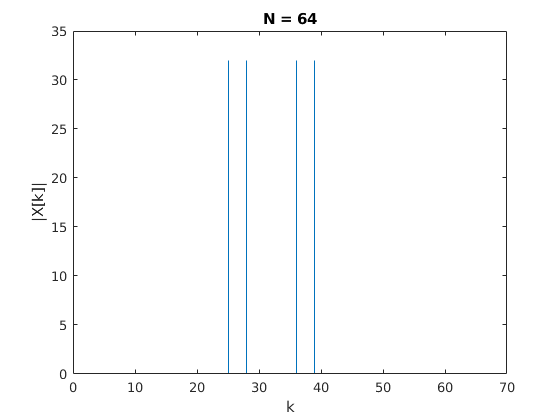

figure
X = fftshift(X);
k=0:length(X)-1;
h = stem(k,abs(X));
set(h, 'Marker', 'none')
ylabel('|X[k]|')
xlabel('k')
title("N = 64")

*There's no leakage in the signal.*

*Recall that the DFT/FFT inherently assumes the input is a periodic signal. If you look at the plot in the first figure, you can see that with ****with N=64****, the signal has just about completed its period at the end, so the last sample is almost equal to the first sample (which is 2). Therefore, the artifacts from the assumed periodicity aren't that strong. *

*In summary there is no leakage because the frequency of our signal is an integer of multiple of ****1/N = 1/64****.*

*The maximum possible ****frequency resolution ****that can be acheived is*

### 
$$\Delta \mathit{\mathbf{f}}=\frac{f_s }{N}$$


*Therefore, in our case, the ****frequency resolution ****is 64/64 = 1Hz.*

*Leakage arises notably with finite length windows, which we always have in practice. However, if we have exactly an integer number of periods of our cosine components, FFT inherent periodization acts as if the cosine were "infinite", and its frequencies exactly fall on discretized bins. --> This is what's happening in this case with N =64*

d) Increase the FFT size to 512, 1024, 2048 & 4096. What effect does the FFT size have on the observed spectrum? Why?

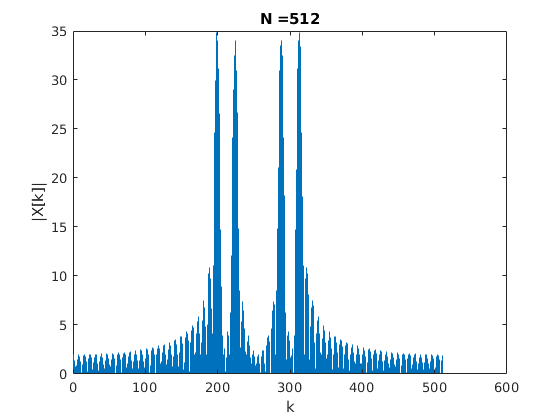

X = fft(x, 512);
figure
X = fftshift(X);
k=0:length(X)-1;
h = stem(k,abs(X));
set(h, 'Marker', 'none')
ylabel('|X[k]|')
xlabel('k')
title("N =512")

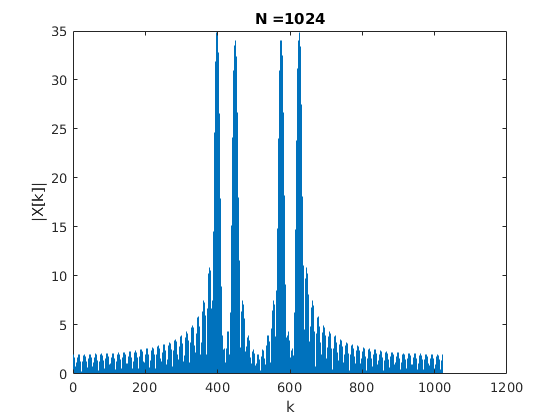

X = fft(x, 1024);
figure
X = fftshift(X);
k=0:length(X)-1;
h = stem(k,abs(X));
set(h, 'Marker', 'none')
ylabel('|X[k]|')
xlabel('k')
title("N =1024")

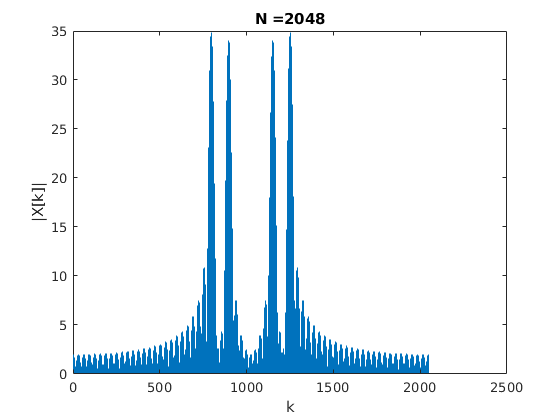

X = fft(x, 2048);
figure
X = fftshift(X);
k=0:length(X)-1;
h = stem(k,abs(X));
set(h, 'Marker', 'none')
ylabel('|X[k]|')
xlabel('k')
title("N =2048")

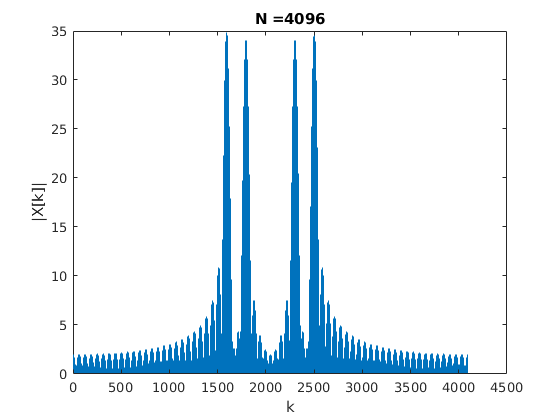

X = fft(x, 4096);
figure
X = fftshift(X);
k=0:length(X)-1;
h = stem(k,abs(X));
set(h, 'Marker', 'none')
ylabel('|X[k]|')
xlabel('k')
title("N =4096")

*There is leakage.*

*We are zero padding the signal more even tho there is no more information to retreive. At this point we are only decreasing the frequency resolution/spacing.*

- *64/512 = 0.125Hz*

- *64/1024 = 0.0625Hz*

- *64/2048 = 0.03125Hz*

- *64/4096=0.015625Hz*

*All extra observed samples are merely an interpolation, done by the window function. We start observing side-lobes of the window spectrum. Since we implicitly multiplied our signal by a rectangular window, this will result in the convolution of the spectrum of our signal with the sinc function.*

*With zero-padding we don't have a pure sine anymore. Neither with non integer period multiple window. We are concatenating chunks of cosines that have abrupt changes at the window boundaries. So the whole periodized signal is not a "infinite cosine" anymore. Hence we can get leakage from the zero padding effect.*

e) While keeping the FFT size fixed to 4096, change the sampling frequency to 32 and 128 samples/second. What effect does the sampling frequency have on the observed spectrum? Explain the behavior.

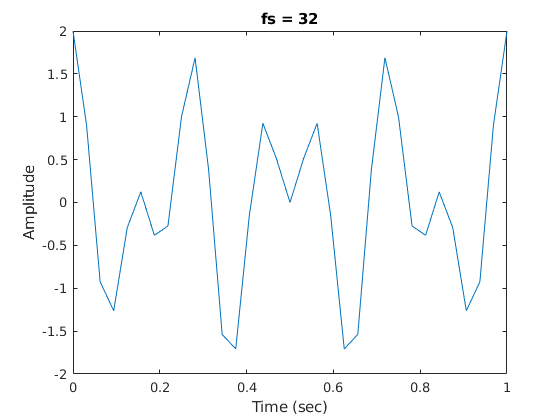

t = 0:1/32:1;   % 1 second sampled at 64 samples/second

x = cos(2*pi*f1*t) + cos(2*pi*f2*t);
figure
plot(t,x)
xlabel('Time (sec)')
ylabel('Amplitude')
title("fs = 32")

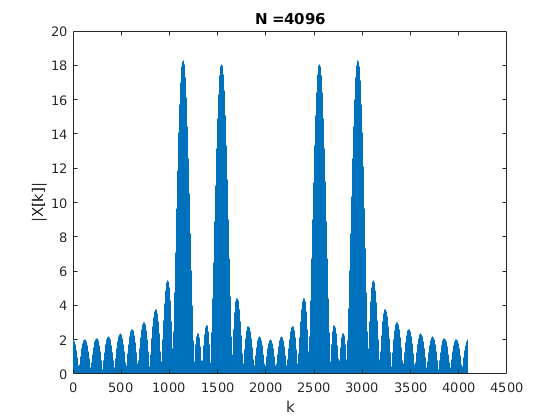

X = fft(x, 4096);
figure
X = fftshift(X);
k=0:length(X)-1;
h = stem(k,abs(X));
set(h, 'Marker', 'none')
ylabel('|X[k]|')
xlabel('k')
title("N =4096")

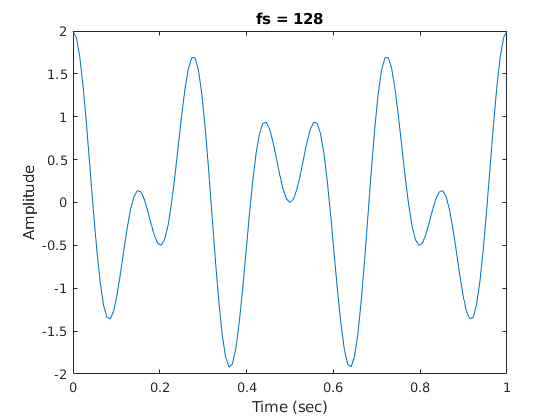


t = 0:1/128:1;   % 1 second sampled at 64 samples/second

x = cos(2*pi*f1*t) + cos(2*pi*f2*t);
figure
plot(t,x)
xlabel('Time (sec)')
ylabel('Amplitude')
title("fs = 128")

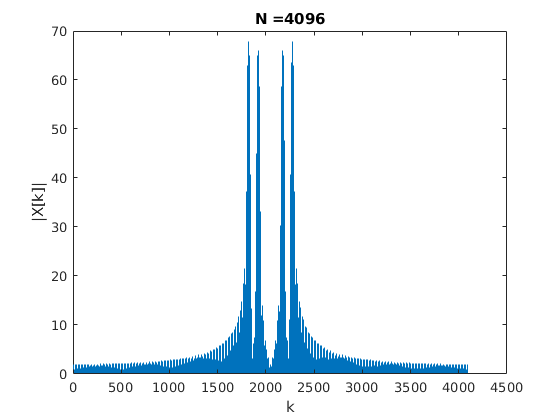

X = fft(x, 4096);
figure
X = fftshift(X);
k=0:length(X)-1;
h = stem(k,abs(X));
set(h, 'Marker', 'none')
ylabel('|X[k]|')
xlabel('k')
title("N =4096")

*The ****frequency resolution ****is*

### 
$$\Delta \mathit{\mathbf{f}}=\frac{f_s }{N}$$


*Therefore, in our case, the ****frequency resolution ****is*

- *32/4096 = 0.0078125*

- *128/4096 = 0.0313*

*It can be seen that when fs = 32Hz, the leakage is much more exaggerated. We can see many more frequencies with higher amplitudes. However when fs = 128Hz the leakage effect is reduced considerebly. This is because we have increased our ****frequency resolution**** with increasing the sampling rate. *

## Problem 6)

#### Repeat parts a) – c) from Problem 5 with a 1-second test signal containing a 3.5 Hz sinusoid and a 7.2 Hz. Describe in how far your results are different and why?

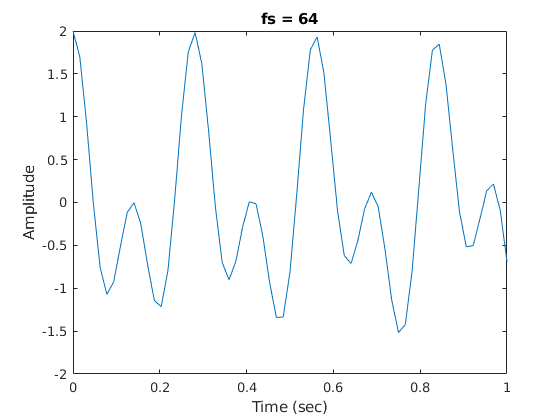

f1 = 3.5;         % 3.5Hz 
f2 = 7.2;         % 7.2Hz
t = 0:1/64:1;   % 1 second sampled at 64 samples/second

x = cos(2*pi*f1*t) + cos(2*pi*f2*t);

plot(t,x)
xlabel('Time (sec)')
ylabel('Amplitude')
title("fs = 64")

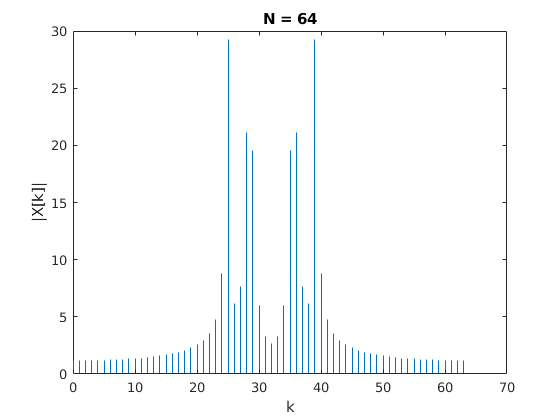

X = fft(x, 64);
figure
X = fftshift(X);
k=0:length(X)-1;
h = stem(k,abs(X));
set(h, 'Marker', 'none')
ylabel('|X[k]|')
xlabel('k')
title("N = 64")

*We can see that our results are much different now as leakage exists in our spectrum now.*

*Again, recall that the DFT/FFT inherently assumes the input is a periodic signal.*

*If we look at our signal in figure 1, we can see that the signal doesn't end at the same value where it started. *

*So when DFT/FFT assumes periodicity the signal looks like this:*

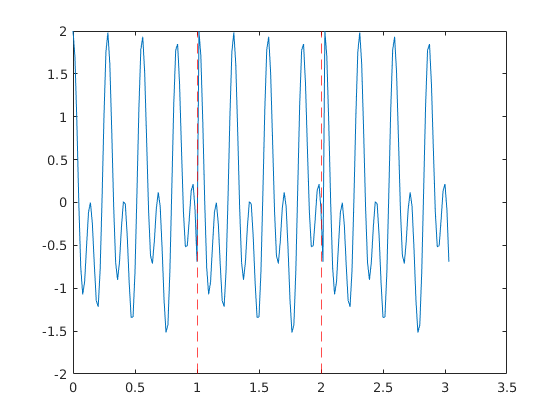

figure
plot(0:1/64:3+2/64, [x x x])
xline(1,'--r');
xline(2,'--r');

You can see how there is a discontinuity at x=1 and x=2. This big jump will spread the spectral peak which results in leakage.

## Problem 7)

#### Create a matrix of Twiddle factors W for a 16-point DFT (show the derivations). Show in MATLAB through an example that you can perform the DFT of a 16-element discrete sequence by matrix multiplication by W, and that the result is equivalent to running a regular 16-point FFT on the same sequence. 

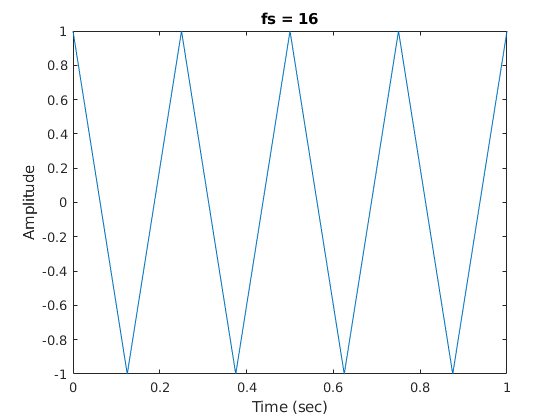

f = 4;         
t = 0:1/16:1;   
x = cos(2*pi*f*t);

figure
plot(t,x)
xlabel('Time (sec)')
ylabel('Amplitude')
title("fs = 16")

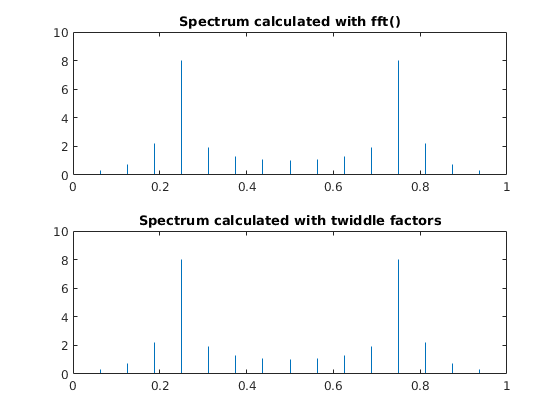

% Creating the twiddle factors
N = length(x);
n = 0:N-1;
w = exp(-1i*2*pi*n/N);  % Twiddle factor equation
W = zeros(N,N);
for k=0:N-1
      W(:,k+1) = w.^k;
end

% Compute the DFT as a product of the twiddle factors matrix with input vector x:
X = x*W;    
X = fftshift(X);

X2 = fft(x);
X2 = fftshift(X2);
figure
subplot(211)
h = stem(t,abs(X));
set(h, 'Marker', 'none')
title("Spectrum calculated with fft()")
subplot(212)
h = stem(t,abs(X2));
set(h, 'Marker', 'none')
title("Spectrum calculated with twiddle factors")

*It can be seen that spectrum of running a regular 16-point fft is equivalent to matrix multiplication of our signal with Twiddle Factors.*